# `iEITBacon Pork sample burn tests`

#### **Details about experiment**

EIT experiments are conducted burn pork skin samples to reconstruct images using the GN-Onestep solver. Several reconstruction priors are tested with various hyperparameters. The optimal hyperparamers are calculated by generalized cross-validantion(GCV) for each test sample and the averaged optimal hyperparamer is used

**Priors used:**

- (NOS) - NOSER prior

- (LAP) - LAPLACE prior

- (TIK) - Tikhonov prior

- (GHPF) - Gaus HPF prior

**Test conducted where objects are placed at:**

- default: no object

- Center (CnC) Tests: Center burn wound

#### **Details about experimental setup**

- Number electrodes = 8

- Stimulation pattern = adjacent 

- Measurement pattern => adjacent

- Stimmulation frequency = 25kHz

- Electrode ring diameter = 80mm

- Burn wound diameter = 20mm

- Sample size = 110mm x 110mm x 10mm square

- Burn time = 30s

- Burn temperature = 150 degrees C

## `Start up`

**Refer to EIDORS website for initial setup and package installation**

[`https://eidors3d.sourceforge.net/`](https://eidors3d.sourceforge.net/)

run startup.m % Ensure EIDORS is initialized

EIDORS:[=== SETTING UP EIDORS version 3.12 ===]
EIDORS:[tested function eidors_var_id: OK]
 EIDORS:[Setting Default Colours]
EIDORS:[Installed EIDORS (Ver: 3.12)]
EIDORS:[Parameter: cache_size=1024 MB]
EIDORS:[Parameter: mapped_colour=127]
EIDORS:[Default background colour: white]
EIDORS:[EIDORS mex folder: C:/Program Files/MATLAB/R2025b/eidors-v3.12-ng/eidors/arch/matlab]
EIDORS:[EIDORS cache folder: C:/Program Files/MATLAB/R2025b/eidors-v3.12-ng/eidors/models/cache (must be writable)]
EIDORS:[EIDORS model cache: C:/Program Files/MATLAB/R2025b/eidors-v3.12-ng/eidors/models/cache]
EIDORS:[New to EIDORS? Have a look at the Tutorials.]


## setup

v_homg = load('iEITBacon_Too_tests\PorkSkin_Test_8_8E\T8-chan8-Pork-DEFAULT-NoObj-F_25kHz-Rd_80mm-med_PorkSkin.txt');
v_inhomg = load('iEITBacon_Too_tests\PorkSkin_Test_8_8E\T8-chan8-Pork-CnC-F_25kHz-Wsize_20mm-Rd_80mm-med_PorkSkin.txt');

disp('Plotting voltages');

Plotting voltages


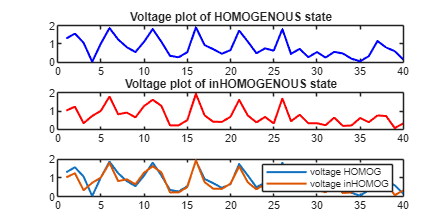

figure('Name', 'Boundary Voltages', 'Position', [100 100 800 400]);

subplot(3,1, 1);
plot(v_homg,'b' , 'LineWidth', 1.5);
title('Voltage plot of HOMOGENOUS state')

subplot(3,1, 2);
plot(v_inhomg, 'r','LineWidth', 1.5);
title('Voltage plot of inHOMOGENOUS state')
subplot(3,1, 3);
plot([v_homg, v_inhomg], 'LineWidth', 1.5);
legend('voltage HOMOG','voltage inHOMOG')

## FEM model


%%measurement instrument dimentions
%%--------------------------------
n_elec = 8;
electrode_ring_radius = 40; %mm
electrode_radius = 0.5;%mm
contact_impedance = 5000;

%%skin dimensions
%%--------------------------------
%wound_radius = 10; %mm
skin_length = 110/2;
skin_width = 110/2;

epidermis_height = 0.02;
dermis_height = 0.18;
subcutanious_Height = 1.8;
skin_height = epidermis_height + dermis_height+subcutanious_Height;
%%Skin conductivity
%%--------------------------------
dermis_conductivity = 0.4

dermis_conductivity = 0.4000

epidermis_conductivity = 0.3;
subcutanious_conductivity = 4e-4;
skin_permativity = 8.854e-12 * 1e3;

%%model parameters
%%--------------------------------

% skin_layers = ['solid top = plane(0,0,1;0,0,1);\n'...
%     'solid subcutanious_lay = orthobrick(-55,-55,-1; 55,55,0.8); tlo subcutanious_lay;\n'...
%     'solid dermis_lay = orthobrick(-55,-55,0.8; 55,55,0.98); tlo solid dermis_lay;\n'...
%     'solid mainobj = top and orthobrick(-55,-55,-1;55,55,1) and not subcutanious_lay and not dermis_lay -maxh=3;\n'
%     ];
% skin_layers = ['solid top = plane(0,0,1;0,0,1);\n'...
%     'solid subcutanious_lay = orthobrick(-55,-55,-1; 55,55,0.8); tlo subcutanious_lay;\n'...
%     'solid dermis_lay = orthobrick(-55,-55,0.8; 55,55,0.98); tlo dermis_lay;\n'...
%     'solid mainobj = top and orthobrick(-55,-55,-1; 55,55,1) and not subcutanious_lay and not dermis_lay -maxh=3;\n'
%     ];

%CUTTING DOWN ON MODEL REALISM
%JUST A SIMPLE BLOCK with coarse mesh
skin_layers = ['solid top = plane(0,0,1;0,0,1);\n'...
    'solid mainobj = top and orthobrick(-55,-55,-1; 55,55,1) -maxh = 10;\n'
    ];

%Electrode positions
ang = linspace(0, 2*pi*(1 - 1/n_elec), n_elec)';
elec_pos = [electrode_ring_radius*cos(ang), electrode_ring_radius*sin(ang), skin_height*ones(n_elec,1), ...
            zeros(n_elec,1), zeros(n_elec,1), ones(n_elec,1)];

Skin_fwdmodel = ng_mk_gen_models(skin_layers, elec_pos, electrode_radius, 'top');

 
C:\Program Files\MATLAB\R2025b\eidors-v3.12-ng\eidors>set TCL_LIBRARY=C:/Program Files/MATLAB/R2025b/eidors-v3.12-ng/eidors/../Netgen-5.3_x64/bin/lib/tcl8.3  
 
C:\Program Files\MATLAB\R2025b\eidors-v3.12-ng\eidors>set TIX_LIBRARY=C:/Program Files/MATLAB/R2025b/eidors-v3.12-ng/eidors/../Netgen-5.3_x64/bin/lib/tix8.1  
 
C:\Program Files\MATLAB\R2025b\eidors-v3.12-ng\eidors>set NETGENDIR=C:/Program Files/MATLAB/R2025b/eidors-v3.12-ng/eidors/../Netgen-5.3_x64/bin  
 
C:\Program Files\MATLAB\R2025b\eidors-v3.12-ng\eidors>"C:/Program Files/MATLAB/R2025b/eidors-v3.12-ng/eidors/../Netgen-5.3_x64/bin/netgen.exe" -batchmode -geofile="C:\Users\higgs\AppData\Local\Temp\tp6cb4d7d7_17b7_4db1_be32_934b897bff0b.geo"  -meshfile="C:\Users\higgs\AppData\Local\Temp\tp6cb4d7d7_17b7_4db1_be32_934b897bff0b.vol"  
NETGEN-5.3 
Developed by Joachim Schoeberl at 
2010-xxxx Vienna University of Technology 
2006-2010 RWTH Aachen University 
1996-2006 Johannes Kepler University Linz 
optfile C:/Program Files/MA

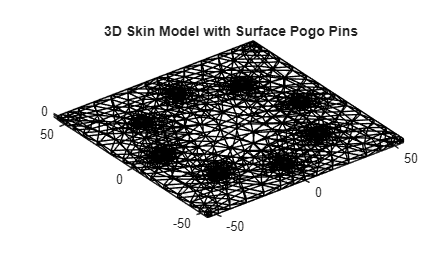


for i = 1:n_elec
    Skin_fwdmodel.electrode(i).z_contact = contact_impedance; 
end


current_A = 600e-6; 
[stim, msel] = mk_stim_patterns(n_elec, 1, '{ad}', '{ad}', {'no_meas_current'}, current_A);
Skin_fwdmodel.stimulation = stim;
Skin_fwdmodel.meas_select = msel;



img_skin = mk_image(Skin_fwdmodel, 0.3); % Background conductivity
% 
% img_skin.elem_data(Skin_fwdmodel.mat_idx{1}) = dermis_conductivity;
% img_skin.elem_data(Skin_fwdmodel.mat_idx{2}) = epidermis_conductivity;
% img_skin.elem_data(Skin_fwdmodel.mat_idx{3}) = subcutanious_conductivity;


v_skin_homg = fwd_solve(img_skin);

figure;
show_fem(Skin_fwdmodel);
title('3D Skin Model with Surface Pogo Pins');
view(3);

## Solve inverse problem


imdl = eidors_obj('inv_model', 'EIT_Inverse');
imdl.reconst_type = 'difference';
imdl.jacobian_bkgnd.value = 1;
imdl.fwd_model = Skin_fwdmodel;
imdl.solve = @inv_solve_diff_GN_one_step;

hp_multipliers = [0.01, 0.1, 1, 10, 100];
hp_labels = {'\lambda/100', '\lambda/10', 'Opt \lambda', '\lambda*10', '\lambda*100'};

imgs_laplace  = cell(1, 5);
imgs_noser    = cell(1, 5);
imgs_tikhonov = cell(1, 5);
imgs_GHPF = cell(1, 5);



priors = {@prior_laplace, @prior_noser, @prior_tikhonov, @prior_gaussian_HPF};
prior_names = {'Laplace', 'NOSER', 'Tikhonov','Gaus_HPF'};

% Use Averaged hyperparameter values of precalculated optimized
% hyperparameter values
for p = 1:4
    fprintf('Computing solutions for %s prior...\n', prior_names{p});
    imdl.RtR_prior = priors{p};
       

        % Store the resulting struct in the appropriate cell array
        switch p
            case 1, imdl.hyperparameter.value = 8.57e+01; %average optimal hyperparameter for laplace prior
                    imgs_laplace  = inv_solve(imdl, v_homg, v_inhomg);

            case 2, imdl.hyperparameter.value = 7.78e-03; %average optimal hyperparameter for NOSER prior
                    imgs_noser    = inv_solve(imdl, v_homg, v_inhomg);

            case 3, imdl.hyperparameter.value = 3.12e-06;%average optimal hyperparameter for tikhonov prior
                    imgs_tikhonov = inv_solve(imdl, v_homg, v_inhomg);

            case 4, imdl.hyperparameter.value = 1.77e-04;%average optimal hyperparameter for GHPF prior
                    imgs_GHPF = inv_solve(imdl, v_homg, v_inhomg);
        end
end

Computing solutions for Laplace prior...


Computing solutions for NOSER prior...
Computing solutions for Tikhonov prior...
Computing solutions for Gaus_HPF prior...



%Custom hyperparameter calculations for samples
% for p = 1:4
% 
%     fprintf('Computing solutions for %s prior...\n', prior_names{priortype});
%     imdl.RtR_prior = priors{p};
%     lambda_base = calc_lambda_regtools(imdl, v_homg, v_inhomg, 'GCV', false);
% 
%     switch p
%             case 1, imgs_laplace{1}  = lambda_base;
%             case 2, imgs_noser{1}    = lambda_base;%inv_solve(imdl, v_homg, v_inhomg);
%             case 3, imgs_tikhonov{1} =  lambda_base;%inv_solve(imdl, v_homg, v_inhomg);
%             case 4, imgs_GHPF{1} = lambda_base;%inv_solve(imdl, v_homg, v_inhomg);
%     end    
% end
% 
% 
% for p = 1:4
% 
%     fprintf('Computing solutions for %s prior...\n', prior_names{priortype});
%     imdl.RtR_prior = priors{p};
%     lambda_base = calc_lambda_regtools(imdl, v_homg, v_inhomg, 'LCC', false);
% 
%     switch p
%             case 1, imgs_laplace{2}  = lambda_base;
%             case 2, imgs_noser{2}    = lambda_base;%inv_solve(imdl, v_homg, v_inhomg);
%             case 3, imgs_tikhonov{2} =  lambda_base;%inv_solve(imdl, v_homg, v_inhomg);
%             case 4, imgs_GHPF{2} = lambda_base;%inv_solve(imdl, v_homg, v_inhomg);
%     end    
% end
% 
% 
% fprintf("hyperparameter values\n")
% fprintf("*******************************\n")
% 
% fprintf("laplace GCV prior \n%s\n", imgs_laplace{1});
% fprintf("laplace LCC prior \n%s\n", imgs_laplace{2});
% 
% fprintf("NOSER GCV prior \n%s\n", imgs_noser{1});
% fprintf("NOSER GCV LCC \n%s\n", imgs_noser{2});
% 
% fprintf("tikhonov GCV prior \n%s\n", imgs_tikhonov{1});
% fprintf("tikhonov LCC prior \n%s\n", imgs_tikhonov{2});
% 
% fprintf("Gaus_HPF GCV prior \n%s\n", imgs_GHPF{1});
% fprintf("Gaus_HPF LCC prior \n%s\n", imgs_GHPF{2});







## Plot reconstructed images

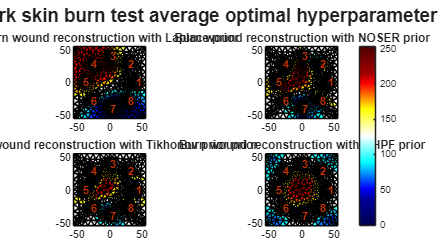


figure('Name', 'Prior vs Hyperparameter Grid', 'Position', [50, 50, 1000, 550]);
t = tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile;
show_fem(imgs_laplace, [0,1]);
view(2);
title(sprintf('Burn wound reconstruction with Laplace prior'));

nexttile;
show_fem(imgs_noser, [0,1]);
view(2);
title(sprintf('Burn wound reconstruction with NOSER prior'));

nexttile;
show_fem(imgs_tikhonov, [0,1]);
view(2);
title(sprintf('Burn wound reconstruction with Tikhonov prior prior'));

nexttile;
show_fem(imgs_GHPF, [0,1]);
view(2);
title(sprintf('Burn wound reconstruction with GHPF prior'));


% Formatting
cb = colorbar;
cb.Layout.Tile = 'east';


title(t, 'Pork skin burn test average optimal hyperparameter', 'FontSize', 14, 'FontWeight', 'bold');

fmdl= mk_library_model('adult_male_16el_lungs');

Continuing in 0
 
C:\Program Files\MATLAB\R2025b\eidors-v3.12-ng\eidors>set TCL_LIBRARY=C:/Program Files/MATLAB/R2025b/eidors-v3.12-ng/eidors/../Netgen-5.3_x64/bin/lib/tcl8.3  
 
C:\Program Files\MATLAB\R2025b\eidors-v3.12-ng\eidors>set TIX_LIBRARY=C:/Program Files/MATLAB/R2025b/eidors-v3.12-ng/eidors/../Netgen-5.3_x64/bin/lib/tix8.1  
 
C:\Program Files\MATLAB\R2025b\eidors-v3.12-ng\eidors>set NETGENDIR=C:/Program Files/MATLAB/R2025b/eidors-v3.12-ng/eidors/../Netgen-5.3_x64/bin  
 
C:\Program Files\MATLAB\R2025b\eidors-v3.12-ng\eidors>"C:/Program Files/MATLAB/R2025b/eidors-v3.12-ng/eidors/../Netgen-5.3_x64/bin/netgen.exe" -batchmode -geofile="C:\Users\higgs\AppData\Local\Temp\tp9adad6c3_f7f9_406d_b058_b0098384a2cb.geo"  -meshfile="C:\Users\higgs\AppData\Local\Temp\tp9adad6c3_f7f9_406d_b058_b0098384a2cb.vol"  
NETGEN-5.3 
Developed by Joachim Schoeberl at 
2010-xxxx Vienna University of Technology 
2006-2010 RWTH Aachen University 
1996-2006 Johannes Kepler University Linz 
optfile C:/

fmdl.electrode = fmdl.electrode([9:16,1:8]);
img = mk_image(fmdl, 1); % background conductivity
img.elem_data([fmdl.mat_idx{2};fmdl.mat_idx{3}]) = 0.3; % lungs








[stim,msel] = mk_stim_patterns(16,1,[0,1],[0,1],{'no_meas_current'},1);
img.fwd_model.stimulation = stim;
img.fwd_model = mdl_normalize(img.fwd_model, 1);
opt.imgsz = [32 32];
opt.distr = 3; % non-random, uniform
opt.Nsim = 500; % 500 hundred targets to train on, seems enough
opt.target_size = 0.03; %small targets
opt.target_offset = 0;
opt.noise_figure = .5; % this is key!
opt.square_pixels = 1;
imdl=mk_GREIT_model(img, 0.25, [], opt);

Continuing in 0
 EIDORS:[mk_GREIT_model: Using 496 points]
  02-May-2026 18:21:29: mk_c2f_circ_mapping: prepare models  Done (0.306 s)
  02-May-2026 18:21:30: mk_c2f_circ_mapping: calculate mapping  184/496

imdl.fwd_model.meas_select = msel;


load montreal_data_1995
img= inv_solve(imdl, zc_resp(:,1), zc_resp);

img.show_slices.img_cols=9;
show_slices(img);


img.calc_colours.ref_level = 0;
img.get_img_data.frame_select = 22;
show_fem(img);
